# The Hydraulic Simulation between Network Model with and without Pump Components

## 1 引言

在地震后，供水管网处于带泄漏的低压供水状态。为了模拟供水管网在低压供水状态下的供水能力，通常在正常运行的供水管网水力模型中增加管道破坏点，对水源模型不做修改。

然而，大量供水管网模型采用固定水头的水源，这种水源在管网正常运行状态下可以较好的模拟管网水力状态与行为，为管网提供充足的水头和水量。但是，由于该水源模型提供固定的水头和无限制的水量，在模拟地震后管网带泄漏供水状态时会产生超出实际的漏水量。

本报告比较分析了同一供水管网在固定水头水源和以水泵提供水头的水源两种模型下的震后供水能力。

## 2 理论

按照以下步骤将固定水头水源模型修改为以水泵提供水头的水源的模型：

- 确定固定水头水源数量；Epanet中Reservoir数量；

- 对R（i），记录正常运行时的供水量Q，以及总水头H;

- 增加一个dummy node以及一个pump；

- dummy node代替水源与管网相连接；

- dummy node和R（i）之间由pump连接；

- 将水源R（i）的总水头和dummy node 的高程和需水量设置为0；

- 设置pump服务曲线，采用单点设计方法。设计点Flow= R(i)的供水量Q，Head=R(i)的原水头H;

- 重复上述2~7步，直到所有固定水头水源修改为由水泵提供水头的水源。

## 3 案例分析

采用GWSL管网，管网模型如图所示，上图为无水泵模型，下图为带水泵模型。

net_nopump = epanet('GWSL_4.inp');

EPANET loaded sucessfuly.
Input File "GWSL_4.inp" loaded sucessfuly.


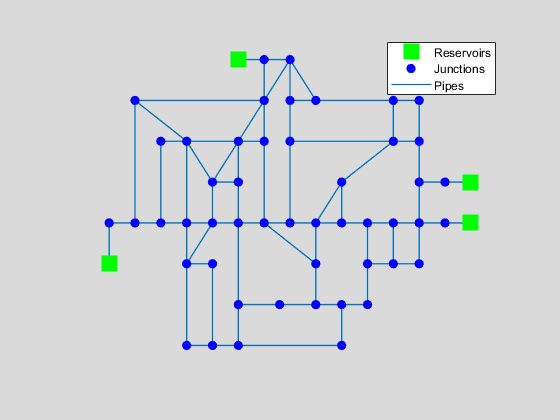

net_nopump.plot;

net_nopump.unload;

EPANET Class is unloaded


net_pump = epanet('GWSL_pump.inp');

EPANET loaded sucessfuly.
Input File "GWSL_pump.inp" loaded sucessfuly.


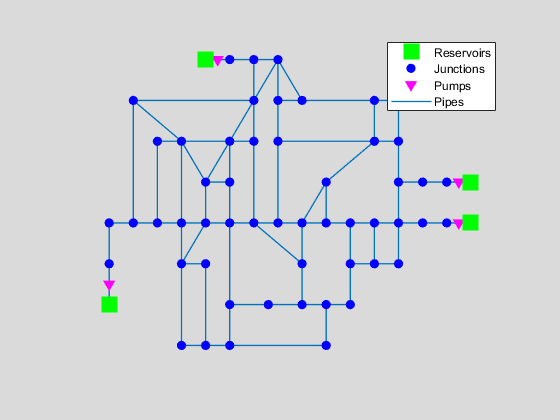

net_pump.plot;

net_pump.unload;

EPANET Class is unloaded


管网参数如下：

No. of Pipes: 78

No. of Junctions 49

No. of Reservoirs 4

No. of tanks 0

Flow Units LPS

Headloss Formula H-W

clear;clc;close all;
data_P = load('sobol-leakType-post_data_GWSL_pump.mat');
data_noP = load('sobol-leakType-post_data_GWSL_4.mat');

### 3.1 收敛性分析

#### （1） 供水满足率SSI=Q/Q0

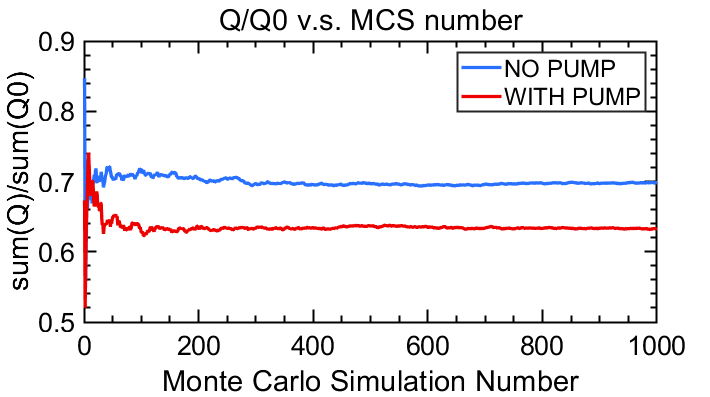

MC_NUM = data_noP.MC_NUM;
X = 1:MC_NUM;
Q_mean_P = cumsum(data_P.SSI_Q)./(1:MC_NUM);
Q_mean_noP = cumsum(data_noP.SSI_Q)./(1:MC_NUM);
f1 = figure(1);
plt1 = Plot(X,Q_mean_noP,X,Q_mean_P);
plt1.XLabel = 'Monte Carlo Simulation Number';
plt1.XLabel = 'Monte Carlo Simulation Number';
plt1.YLabel = 'sum(Q)/sum(Q0)';
plt1.Title = 'Q/Q0 v.s. MCS number';
plt1.Legend = {'NO PUMP','WITH PUMP'};
plt1.LegendBox = 'on';

close(f1);
epsilon_Q = (Q_mean_noP(end)-Q_mean_P(end))/Q_mean_P(end)

epsilon_Q = 0.1024

#### （2）供水满足率SSI的变异系数

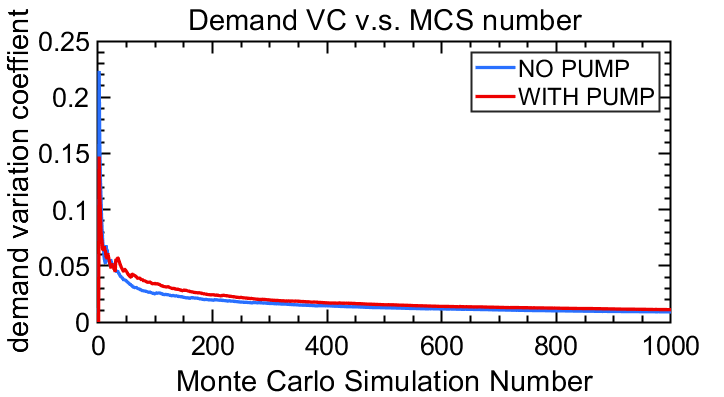

Q_sd_p = sqrt(cumsum((data_P.SSI_Q-Q_mean_P).^2)./(1:MC_NUM));
Q_vc_p = Q_sd_p./Q_mean_P;
Q_sd_noP = sqrt(cumsum((data_noP.SSI_Q-Q_mean_noP).^2)./(1:MC_NUM));
Q_vc_noP = Q_sd_noP./Q_mean_noP;
Q_mean_vc_p = Q_vc_p./(1:MC_NUM).^0.5;%均值的变异系数(HOU 博士论文第3章)
Q_mean_vc_noP = Q_vc_noP./(1:MC_NUM).^0.5;
f3 = figure(3);
p3 = Plot(X,Q_mean_vc_noP,X,Q_mean_vc_p);
p3.XLabel = 'Monte Carlo Simulation Number';
p3.YLabel = 'demand variation coeffient';
p3.Title = 'Demand VC v.s. MCS number';
p3.Legend = {'NO PUMP','WITH PUMP'};
p3.LegendBox = 'on';
p3.LegendLoc = 'northeast';

close(f3);
epsilon_vc = (Q_mean_vc_noP(end)-Q_mean_vc_p(end))/Q_mean_vc_p(end)

epsilon_vc = -0.1823

#### （3）节点平均水压 H

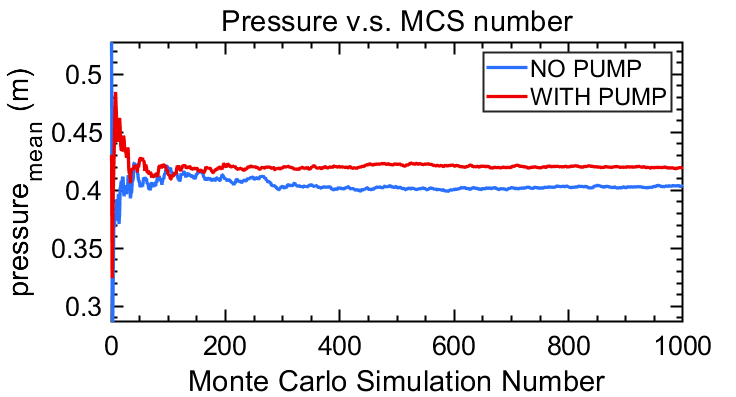

H_mean_noP = cumsum(data_noP.SSI_H)./(1:MC_NUM);
H_mean_P = cumsum(data_P.SSI_H)./(1:MC_NUM);
f2 = figure(2);
p2 = Plot(X,H_mean_noP,X,H_mean_P);
p2.XLabel = 'Monte Carlo Simulation Number';
p2.YLabel = 'pressure_m_e_a_n (m)';
p2.Title = 'Pressure v.s. MCS number';
p2.Legend = {'NO PUMP','WITH PUMP'};
p2.LegendBox = 'on';

close(f2)
epsilon_H = (H_mean_noP(end)-H_mean_P(end))/H_mean_P(end)

epsilon_H = -0.0390

#### （4）节点平均水压 H的变异系数

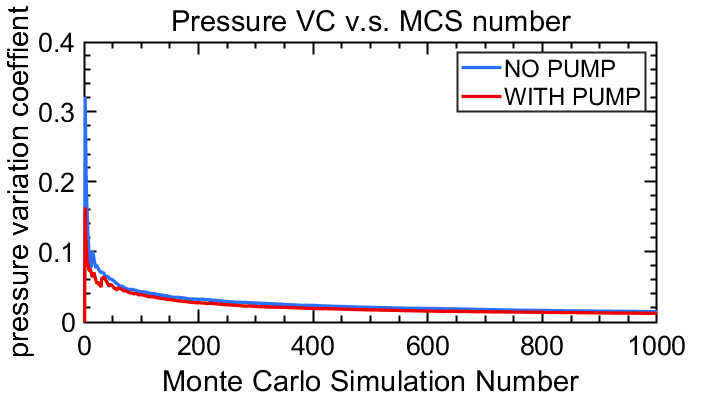

H_sd_noP = sqrt(cumsum((data_noP.SSI_H-H_mean_noP).^2)./(1:MC_NUM));
H_vc_noP = H_sd_noP./H_mean_noP;
H_sd_p = sqrt(cumsum((data_P.SSI_H-H_mean_P).^2)./(1:MC_NUM));
H_vc_p = H_sd_p./H_mean_P;
H_mean_vc_noP = H_vc_noP./(1:MC_NUM).^0.5;%均值的变异系数(HOU 博士论文第3章)
H_mean_vc_P = H_vc_p./(1:MC_NUM).^0.5;
f4 = figure(4);
p4 = Plot(X,H_mean_vc_noP,X,H_mean_vc_P);
p4.XLabel = 'Monte Carlo Simulation Number';
p4.YLabel = 'pressure variation coeffient';
p4.Title = 'Pressure VC v.s. MCS number';
p4.Legend = {'NO PUMP','WITH PUMP'};
p4.LegendBox = 'on';
p4.LegendLoc = 'northeast';

close(f4)
epsilon_vc_H = (H_mean_vc_noP(end)-H_mean_vc_P(end))/H_mean_vc_P(end)

epsilon_vc_H = 0.1993

### 3.2 统计特征分析

#### （1） 供水满足率的箱型图

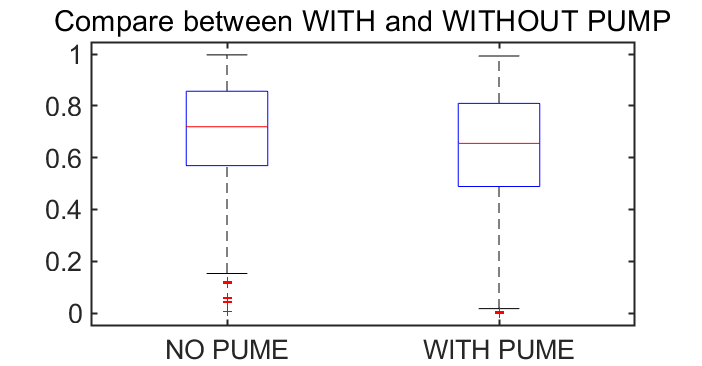

f5 = figure(5);
f5.Units = 'inches';
bpt1 = boxplot([data_noP.SSI_Q',data_P.SSI_Q'],'Labels',{'NO PUME','WITH PUME'},"Widths",0.3);
f5.Position = [7 4.1250 7.3125 3.8094];
f5.CurrentAxes.Box = 'on';
f5.CurrentAxes.LineWidth = 1.5;
f5.CurrentAxes.Title.String = 'Compare between WITH and WITHOUT PUMP';
f5.CurrentAxes.FontSize = 20;
f5.CurrentAxes.FontName = 'Arial';

% f5.CurrentAxes.Units = 'inches';
% pos5 = f5.CurrentAxes.Position;
% height = 3;width = 6;
% f5.CurrentAxes.Position = [pos5(1),pos5(2),width,height];
% close(f5);

#### （2）供水满足涨的频数分布图

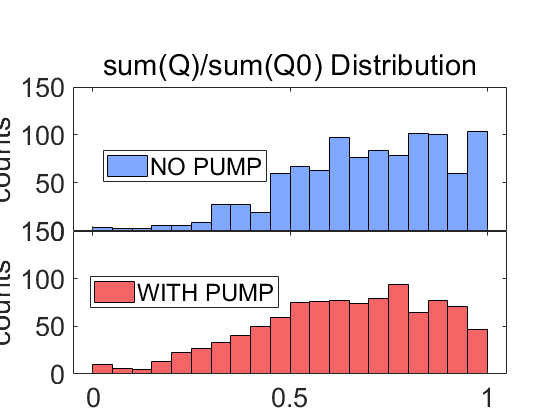

f7 = figure(7);
% f = f7;
axe71 = subplot(2,1,1);
ph1 = histogram(data_noP.SSI_Q);
ph1.BinLimits = [0,1];
ph1.NumBins = 20;
ph1.FaceColor = [0.16,0.44,1.00];
axe71.Title.String = 'sum(Q)/sum(Q0) Distribution';
axe71.FontName = 'Arial';
axe71.FontSize = 20;
% axe1.XLabel.String = 'sum(Q)/sum(Q0)';
axe71.YLabel.String = 'counts';
% axe1.Title.String = 'random';
% axe1.Title.Position =  [0.1,90,0]
axe71.XTickLabel = '';
len1 = legend('NO PUMP');
len1.Position = [0.25,0.58,0.16,0.05];
axe72 = subplot(2,1,2);
ph2 = histogram(data_P.SSI_Q);
ph2.BinLimits = [0,1];
ph2.NumBins = 20;
ph2.FaceColor = [0.93,0,0];
axe72.FontName = 'Arial';
axe72.FontSize = 20;
axe72.XLabel.String= 'sum(Q)/sum(Q0)';
axe72.YLabel.String = 'counts';
% axe2.Title.String = 'sobol';
% axe2.Title.Position =  [0.1,90,0]
len2 = legend('WITH PUMP');
len2.Position = [0.25,0.28,0.16,0.05];
pos7 = axe72.Position;
axe72.YLim = [0,150];
axe71.Position = [pos7(1),pos7(2)+pos7(4),pos7(3),pos7(4)];
axe72.Position = pos7;
axe71.YAxis.Limits = axe72.YLim;

% close(f);

#### （3）节点平均压力的箱型图

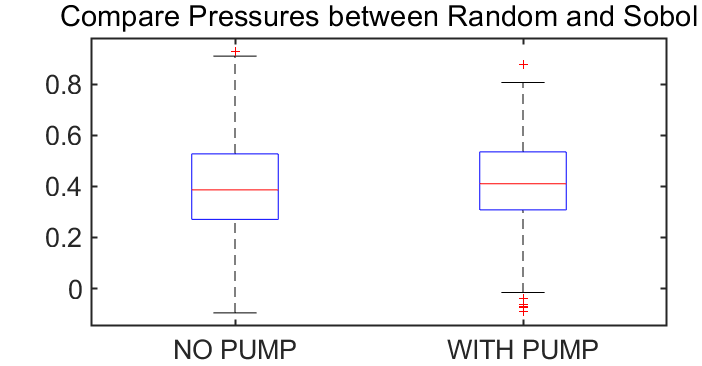

f6 = figure(6);
f = f6;
bpt2 = boxplot([data_noP.SSI_H',data_P.SSI_H'],'Labels',{'NO PUMP','WITH PUMP'},"Widths",0.3);
f.Units = 'inches';
f.Position = [7 4.1250 7.3125 3.8094];
f.CurrentAxes.Box = 'on';
f.CurrentAxes.LineWidth = 1.5;
f.CurrentAxes.Title.String = 'Compare Pressures between Random and Sobol';
f.CurrentAxes.FontSize = 20;
f.CurrentAxes.FontName = 'Arial';
f.CurrentAxes.Units = 'inches';
pos7 = f.CurrentAxes.Position;
height = 3;width = 6;
f.CurrentAxes.Position = [pos7(1),pos7(2),width,height];

#### （4）节点平均压力的频数分布图

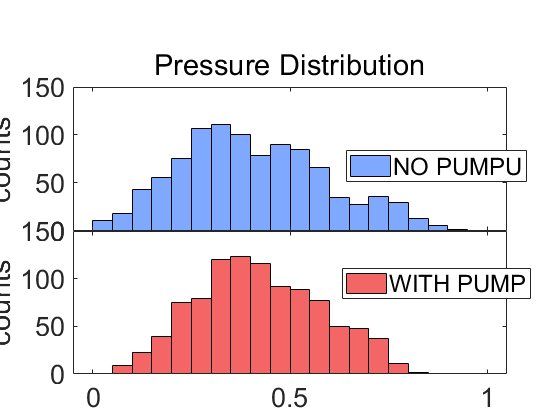

f8 = figure(8);
f = f8;
axe81 = subplot(2,1,1);
ph1 = histogram(data_noP.SSI_H);
ph1.BinLimits = [0,1];
ph1.NumBins = 20;
ph1.FaceColor = [0.16,0.44,1.00];
axe81.Title.String = 'Pressure Distribution';
axe81.FontName = 'Arial';
axe81.FontSize = 20;
axe81.YLabel.String = 'counts';
axe81.XTickLabel = '';
len1 = legend('NO PUMPU');
len1.Position = [0.70,0.58,0.16,0.05];
axe82 = subplot(2,1,2);
ph2 = histogram(data_P.SSI_H);
ph2.BinLimits = [0,1];
ph2.NumBins = 20;
ph2.FaceColor = [0.93,0,0];
axe82.FontName = 'Arial';
axe82.FontSize = 20;
axe82.XLabel.String= 'Pressure (m)';
axe82.YLabel.String = 'counts';
len2 = legend('WITH PUMP');
len2.Position = [0.70,0.30,0.16,0.05];
pos8 = axe82.Position;
axe82.YLim = [0 150];
axe81.Position = [pos8(1),pos8(2)+pos8(4),pos8(3),pos8(4)];
axe82.Position = pos8;
axe81.YLim = axe82.YLim;

## 4 结论

通过上述分析，可以得到以下结论：

- 加水泵后，1000次模拟的供水管网供水满足率均值下降，方差增大；

- 加水泵后，1000次模拟的供水管网平均节点压力均值上升，方差减小。